# fStack:

clear all
clf

filtersize = 7;
logstd = 1;
dilatesize = 1;
colorimg = true;
sobel = false;

% Images paths:
imgDir = 'images/HelmetBokae/';
imagefiles = dir('images/HelmetBokae/*.png');
GroundTruth = im2double(imread("HelmetGT.png"));


%blendsize = 31;
%blendstd = 5;
%logthreshold = 0;
Sobel3x3 = [1 2 1; 0 0 0; -1 -2 -1];
Sobel5x5 = [2 2 4 2 2; 1 1 2 1 1; 0 0 0 0 0; -1 -1 -2 -1 -1; -2 -2 -4 -2 -2];
Sobel7x7 = [4 4 4 8 4 4 4; 2 2 2 4 2 2 2; 1 1 1 2 1 1 1; 0 0 0 0 0 0 0;  -1 -1 -1 -2 -1 -1 -1; -2 -2 -2 -4 -2 -2 -2; -4 -4 -4 -8 -4 -4 -4];

% Get all images and put them in array:
% img1 = im2double(imread("1-1.jpg"));
% img2 = im2double(imread("1-2.jpg"));
% img3 = im2double(imread("1-3.jpg"));
% 
% imgSize = size(img1);
% nImages = 3;
% 
% imgArray = zeros(imgSize(1), imgSize(2), 3,nImages);
% imgArray(:,:,:,1) = img1;
% imgArray(:,:,:,2) = img2;
% imgArray(:,:,:,3) = img3;
% 
% testImg = imgArray(:,:,:,2);
% 
% imshow(testImg);

## Image read:

if(colorimg)
    %Color image read:
    %imgDir = 'images/3Balls/';
    %imagefiles = dir('images/3Balls/*.png');
    nImages = length(imagefiles);

        for ii=1:nImages
           currentfilename = imagefiles(ii).name;
           currentimage = im2double(imread(strcat(imgDir,currentfilename)));   
           imgArray(:,:,:,ii) = currentimage;
        end
    imgSize = size(imgArray(:,:,:,1));
    greyImgArray = zeros(imgSize(1), imgSize(2),nImages);
    for currimg = 1:nImages
            greyImgArray(:,:,currimg) = rgb2gray(imgArray(:,:,:,currimg));
    end
    
else
    %Greyscale Read:
    %imgDir = 'images/KaktusFocus/KaktusFocus/';
    %imagefiles = dir('images/KaktusFocus/KaktusFocus/*.jpg');
    nImages = length(imagefiles);
    
    for ii=1:nImages
       currentfilename = imagefiles(ii).name;
       currentimage = im2double(imread(strcat(imgDir,currentfilename)));   
       imgArray(:,:,ii) = currentimage;
    end
    imgSize = size(imgArray(:,:,1));
    
    greyImgArray = zeros(imgSize(1), imgSize(2),nImages);
    greyImgArray = imgArray;
end

% If image is RGB make it greyscale for calculations:
% greyImgArray = zeros(imgSize(1), imgSize(2),nImages);
% if (size(imgSize)>2)
%     imgArrayCopy = imgArray;
%     colorimg = true;
%     
%     greyImgArray(:,:,1) = rgb2gray(imgArray(:,:,:,1));
%     greyImgArray(:,:,2) = rgb2gray(imgArray(:,:,:,2));
%     greyImgArray(:,:,3) = rgb2gray(imgArray(:,:,:,3));
% else
%     colorimg = false;
%     greyImgArray = imgArray;
%    
% 
% end
% greyImgArray

% Filter image:
filteredImgArray = zeros(imgSize(1), imgSize(2), nImages);

if(sobel)
    sobelFilter = fspecial("sobel");
    if(filtersize == 3)
        sobelFilter = Sobel3x3;
    elseif (filtersize == 5)
        sobelFilter = Sobel5x5;
    else
        sobelFilter = Sobel7x7;
    end

    se = strel('ball', dilatesize, dilatesize);
    for i = 1:nImages
        %filteredImgArray(:,:,i) = imfilter(greyImgArray(:,:,i),sobelFilter);
        xGrad = imfilter(greyImgArray(:,:,i),sobelFilter);
        yGrad = imfilter(greyImgArray(:,:,i),sobelFilter');
        gradImg = sqrt(xGrad.^2 + yGrad.^2);
        filteredImgArray(:,:,i) = imdilate(gradImg, se, 'same');
    end
else
    % Image Processing Toolbox:
    %fspecial('log',hsize,sigma) returns a rotationally symmetric 
    % Laplacian of Gaussian filter of size hsize with standard deviation sigma.
    logfilter = fspecial('log', [filtersize filtersize], logstd);
    se = strel('ball', dilatesize, dilatesize);
    
    for i = 1:nImages
        filteredImgArray(:,:,i) = imfilter(greyImgArray(:,:,i),logfilter);
        filteredImgArray(:,:,i) = imdilate(filteredImgArray(:,:,i), se, 'same');
    end
end


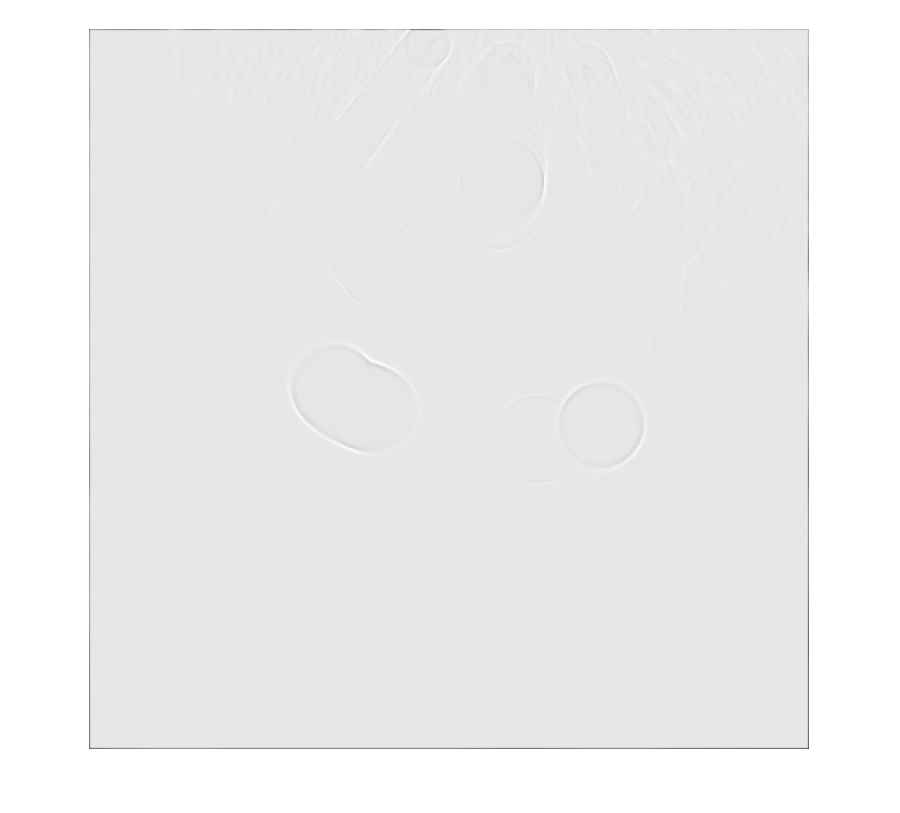


testImg = filteredImgArray(:,:,25);
testImg = testImg - min(min(testImg));
testImg = testImg./max(max(testImg));
%testImg = normalize(testImg,'range',[0 1])
imshow(testImg);

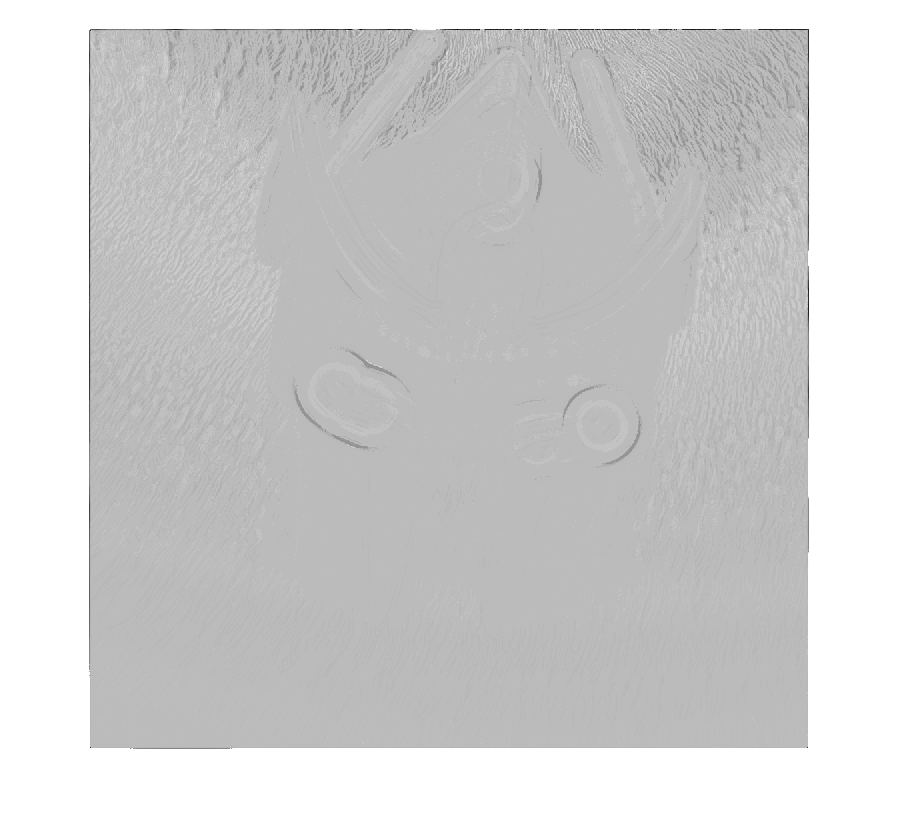

%Depth Map:*(nImages-i)
depthMap = zeros(imgSize(1), imgSize(2));
for i = 1:nImages
    imageToadd = filteredImgArray(:,:,i);
    imageToadd = imageToadd - min(min(imageToadd));
    imageToadd = imageToadd./max(max(imageToadd));
    imageMask = imageToadd > 0.54;
    imageMask2 = imageToadd < 0.8;
    imageToadd = imageToadd.*imageMask.*imageMask2;
    depthMap = depthMap - imageToadd*i*i;
end

%depthMap = depthMap - min(min(depthMap));
%depthMap = depthMap./max(max(depthMap));

imshow(depthMap,[])


% fmap = ones(imgSize(1),imgSize(2), nImages, 'single');
% logresponse = zeros(imgSize(1),imgSize(2), nImages, 'single') + logthreshold;
% 
% for i = 1:nImages 
%     index = filteredImgArray(:,:,i) > logresponse;
%     logresponse(:,:,i) = filteredImgArray(:,:,i).*(index(:,:,i));
%     fmap(index) = i;
% end
% 
% testImg = fmap(:,:,2);
% imshow(testImg, []);

% Smooth focal plane image
% fmap(:,:,1) = imfilter(fmap(:,:,1),fspecial('gaussian', [blendsize blendsize], blendstd));
% fmap(:,:,2) = imfilter(fmap(:,:,2),fspecial('gaussian', [blendsize blendsize], blendstd));
% fmap(:,:,3) = imfilter(fmap(:,:,3),fspecial('gaussian', [blendsize blendsize], blendstd));
% fmap(fmap < 1) = 1;
% 
% testImg = fmap(:,:,2);
% imshow(testImg, []);

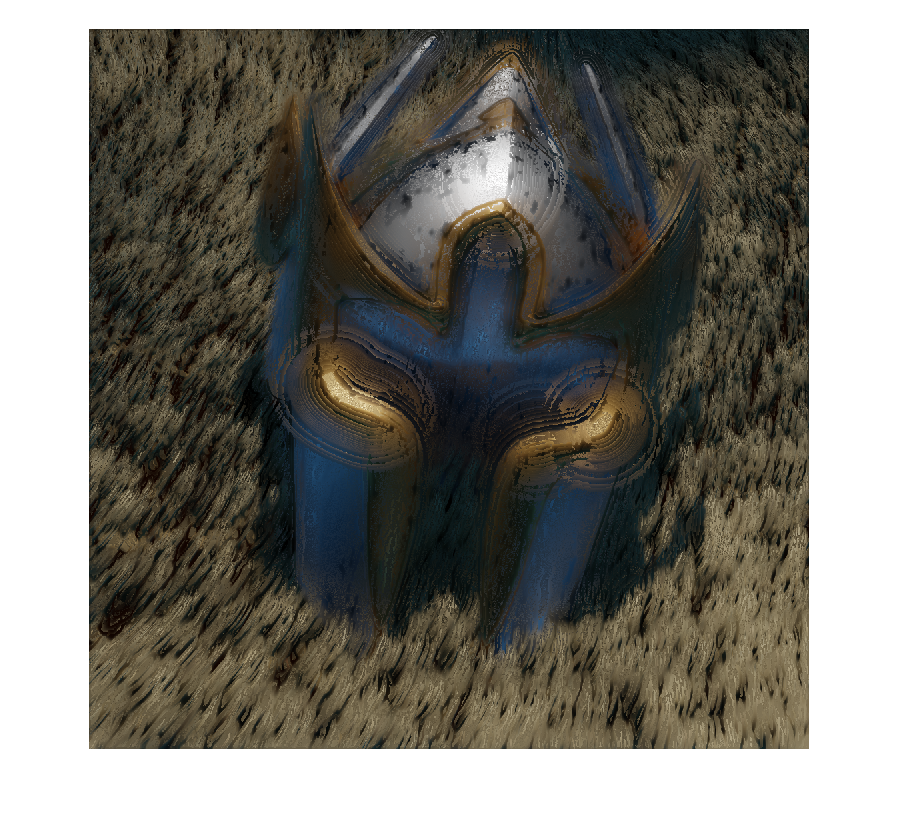

if(colorimg)
    out = zeros(imgSize(1), imgSize(2), imgSize(3));
    for i = 1:imgSize(1)
        for j = 1:imgSize(2)
            % Create highestvalue
            currpixelVec = filteredImgArray(i,j,:);
            [highestValue, highestIndex] = max(currpixelVec);
    
            % Assign pixel value
            out(i,j,:) =  imgArray(i,j,:,highestIndex);
        end
    end
else
    out = zeros(imgSize(1), imgSize(2));
    for i = 1:imgSize(1)
        for j = 1:imgSize(2)
            % Create highestvalue
            currpixelVec = filteredImgArray(i,j,:);
            [highestValue, highestIndex] = max(currpixelVec);
    
            % Assign pixel value
            out(i,j) =  imgArray(i,j,highestIndex);
        end
    end
end


imshow(out, []);

## Measures:

MAE=sum(abs(GroundTruth(:)-out(:)))/numel(GroundTruth)

MAE = 0.1105

ssim(out,GroundTruth)

ans = 0.3931

snr(GroundTruth, out)

ans = 0.6246